# **Cinemática Inversa Manipulador 4R**

# **Felipe Forero - Iván Hernández - Juan Ramirez - Felipe Zuleta**

Para el desarrollo del modelo cinemático inverso del manipulador, se utiliza un acercamiento geométrico del mismo.

Para encontrar las variables articulares del manipulador, se debe partir de la ubicación del TCP de la herramienta, para el desarrollo de este análisis comenzaremos observando el manipulador desde una vista superior, en donde las coordenadas x e y de la herramienta saltan a la vista, veáse la siguiente figura.

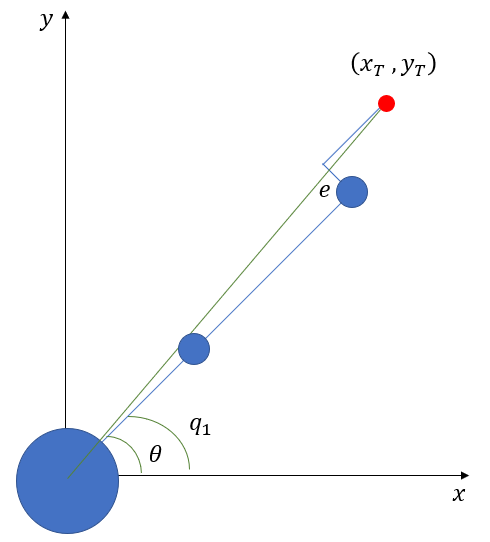

Para continuar con el análisis, se debe observar el manipulador desde una vista lateral, con lo que se tiene.

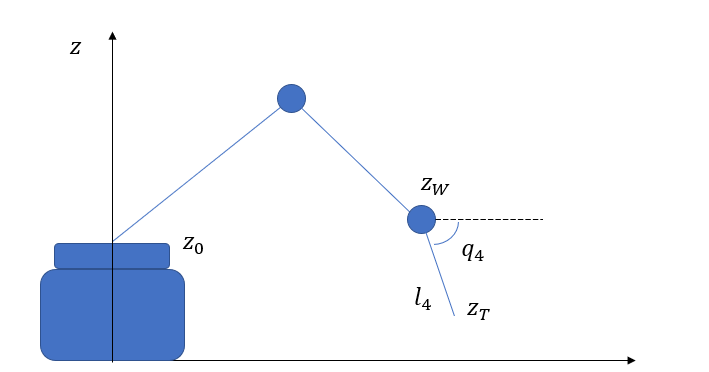

Con esta imagen podemos observar de mejor manera la vista superior del manipulador con lo que podremos tener en cuenta la longitud del eslabón desde dicha vista, teniendo en cuenta su orientación $q_4$.

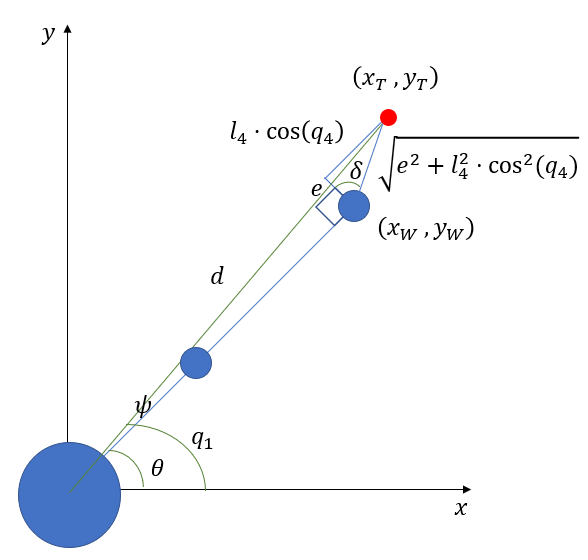

Individualizando el triángulo que se forma, se obtiene.

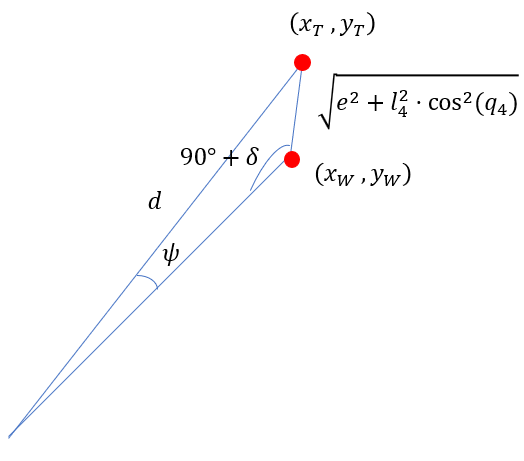

De las figuras anteriores, se determinan los ángulos $\theta$, $\delta$, $q_1$ y $\psi$; así como la distancia $d$ pueden determinarse fácilmente.


$$d=\sqrt{x_T^2 +y_T^2 }$$



$$\delta =\textrm{atan2}\left(l_4 \cdot \cos \left(q_4 \right)\;,e\right)$$



$$\psi =\textrm{asin}\;\left(\frac{\sin \left(90+\delta \right)\cdot \sqrt{e^2 +l_4^2 \cdot \cos^2 \left(q_4 \right)}}{d}\right)$$



$$\theta \;=\textrm{atan2}\;\left(y_T \;,x_T \right)$$



$$q_1 =\theta -\psi$$


syms xT yT zT q4
e = 50e-03;
l2 = 179.81e-3;
l3 = 125.3264e-3; %m
l4 = 63.75e-03;
z0 = 123.85e-03;
theta = atan2(yT,xT)

$$theta = \text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)$$

d = sqrt(xT^2 + yT^2)

$$d = \sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}$$

delta = atan2(l4*cos(q4),e)

$$delta = \mathrm{atan}\left(\frac{51\,\cos\left(q_{4}\right)}{40}\right)$$

d2 = sqrt(e^2+l4^2*(cos(q4))^2)

$$d2 = \sqrt{\frac{585693131539533\,{\cos\left(q_{4}\right)}^{2}}{144115188075855872}+\frac{1}{400}}$$

sigma = pi/2 + delta

$$sigma = \frac{\pi }{2}+\mathrm{atan}\left(\frac{51\,\cos\left(q_{4}\right)}{40}\right)$$

psi = asin((sin(sigma)*d2)/d)

$$psi = \mathrm{asin}\left(\frac{\sin\left(\frac{\pi }{2}+\mathrm{atan}\left(\frac{51\,\cos\left(q_{4}\right)}{40}\right)\right)\,\sqrt{\frac{585693131539533\,{\cos\left(q_{4}\right)}^{2}}{144115188075855872}+\frac{1}{400}}}{\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}}\right)$$

q1 = theta-psi

$$q1 = \text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\mathrm{asin}\left(\frac{\sin\left(\frac{\pi }{2}+\mathrm{atan}\left(\frac{51\,\cos\left(q_{4}\right)}{40}\right)\right)\,\sqrt{\frac{585693131539533\,{\cos\left(q_{4}\right)}^{2}}{144115188075855872}+\frac{1}{400}}}{\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}}\right)$$

El objetivo a continuación, será conocer la posición de la muñeca, para lo que se comienza por conocer su altura.


$$z_W =z_T -l_4 \cdot \sin \;\left(q_4 \right)$$


zW = zT-l4*sin(q4)

$$zW = \mathrm{zT}-\frac{51\,\sin\left(q_{4}\right)}{800}$$

Desde la vista superior se tiene.

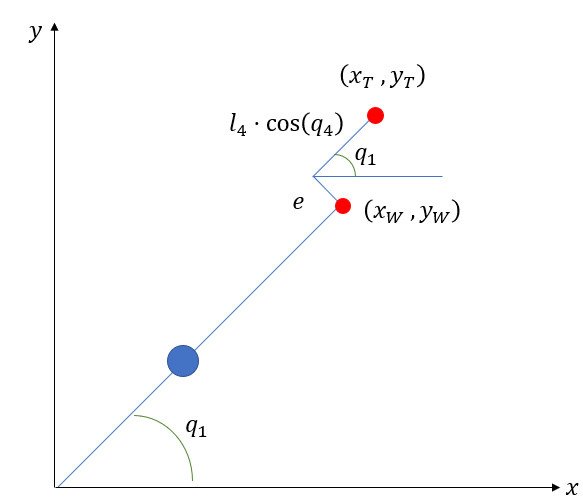

De donde, se encuentra la posición de la muñeca


$$x_W =x_T -l_4 \cdot \cos \left(q_4 \right)\cdot \cos \left(q_1 \right)+e\cdot \sin \left(q_1 \right)$$



$$y_W =y_T -l_4 \cdot \cos \left(q_4 \right)\cdot \sin \left(q_1 \right)-e\cdot \cos \left(q_1 \right)$$


xW = xT - l4*cos(q4)*cos(q1) + e*sin(q1)

$$xW = \begin{array}{l} \mathrm{xT}+\frac{\sin\left(\sigma_{1}\right)}{20}-\frac{51\,\cos\left(\sigma_{1}\right)\,\cos\left(q_{4}\right)}{800}\\ \mathrm{where}\\ \sigma_{1}=\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\mathrm{asin}\left(\frac{\sin\left(\frac{\pi }{2}+\mathrm{atan}\left(\frac{51\,\cos\left(q_{4}\right)}{40}\right)\right)\,\sqrt{\frac{585693131539533\,{\cos\left(q_{4}\right)}^{2}}{144115188075855872}+\frac{1}{400}}}{\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}}\right) \end{array}$$

yW = yT - l4*cos(q4)*sin(q1) - e*cos(q1)

$$yW = \begin{array}{l} \mathrm{yT}-\frac{\cos\left(\sigma_{1}\right)}{20}-\frac{51\,\sin\left(\sigma_{1}\right)\,\cos\left(q_{4}\right)}{800}\\ \mathrm{where}\\ \sigma_{1}=\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\mathrm{asin}\left(\frac{\sin\left(\frac{\pi }{2}+\mathrm{atan}\left(\frac{51\,\cos\left(q_{4}\right)}{40}\right)\right)\,\sqrt{\frac{585693131539533\,{\cos\left(q_{4}\right)}^{2}}{144115188075855872}+\frac{1}{400}}}{\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}}\right) \end{array}$$

De esta manera, los ángulos 2 y 3 pueden ser encontrados a través del teorema del coseno, para lo cual nos basamos en la figura

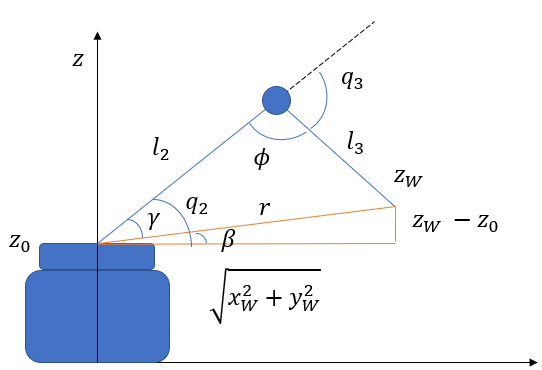

De esta manera, se encuentran los ángulos de interés a continuación.


$$\beta =\textrm{atan2}\;\left(z_W -z_0 \;,\sqrt{\;x_w^2 +y_w^2 }\right)$$



$$r^2 =x_W^2 +y_W^2 +{\left(z_W -z_0 \right)}^2$$



$$\gamma =\cos^{-1} \left(\frac{l_2^2 +r^2 -l_3^2 }{2\cdot r\cdot l_2 }\right)$$



$$\phi \;{=\;\cos }^{-1} \left(\frac{l_2^2 +l_3^2 -r^2 }{2\cdot l_2 \cdot l_3 }\right)$$



$$q_2 =\beta +\gamma$$



$$q_3 =-\left(\pi -\phi \right)\;$$


beta = atan2(zW-z0, sqrt(xW^2+yW^2))

$$beta = \begin{array}{l} \text{angle}\left(\mathrm{zT}\,\mathrm{i}-\frac{51\,\sin\left(q_{4}\right)\,\mathrm{i}}{800}+\sqrt{{\left(\mathrm{xT}+\frac{\sin\left(\sigma_{1}\right)}{20}-\frac{51\,\cos\left(\sigma_{1}\right)\,\cos\left(q_{4}\right)}{800}\right)}^{2}+{\left(-\mathrm{yT}+\frac{\cos\left(\sigma_{1}\right)}{20}+\frac{51\,\sin\left(\sigma_{1}\right)\,\cos\left(q_{4}\right)}{800}\right)}^{2}}-\frac{2477}{20000}\,\mathrm{i}\right)\\ \mathrm{where}\\ \sigma_{1}=\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\mathrm{asin}\left(\frac{\sin\left(\frac{\pi }{2}+\mathrm{atan}\left(\frac{51\,\cos\left(q_{4}\right)}{40}\right)\right)\,\sqrt{\frac{585693131539533\,{\cos\left(q_{4}\right)}^{2}}{144115188075855872}+\frac{1}{400}}}{\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}}\right) \end{array}$$

r = sqrt(xW^2 + yW^2 + (zW-z0)^2)

$$r = \begin{array}{l} \sqrt{{\left(\mathrm{xT}+\frac{\sin\left(\sigma_{1}\right)}{20}-\frac{51\,\cos\left(\sigma_{1}\right)\,\cos\left(q_{4}\right)}{800}\right)}^{2}+{\left(-\mathrm{yT}+\frac{\cos\left(\sigma_{1}\right)}{20}+\frac{51\,\sin\left(\sigma_{1}\right)\,\cos\left(q_{4}\right)}{800}\right)}^{2}+{\left(\frac{51\,\sin\left(q_{4}\right)}{800}-\mathrm{zT}+\frac{2477}{20000}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\mathrm{asin}\left(\frac{\sin\left(\frac{\pi }{2}+\mathrm{atan}\left(\frac{51\,\cos\left(q_{4}\right)}{40}\right)\right)\,\sqrt{\frac{585693131539533\,{\cos\left(q_{4}\right)}^{2}}{144115188075855872}+\frac{1}{400}}}{\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}}\right) \end{array}$$

gamma = acos((l2^2+r^2-l3^2)/2*r*l2)

$$gamma = \begin{array}{l} \mathrm{acos}\left(\frac{17981\,\sqrt{\sigma_{2}+\sigma_{1}+{\left(\frac{51\,\sin\left(q_{4}\right)}{800}-\mathrm{zT}+\frac{2477}{20000}\right)}^{2}}\,\left(\frac{\sigma_{2}}{2}+\frac{\sigma_{1}}{2}+\frac{{\left(\frac{51\,\sin\left(q_{4}\right)}{800}-\mathrm{zT}+\frac{2477}{20000}\right)}^{2}}{2}+\frac{4791809701450731}{576460752303423488}\right)}{100000}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(-\mathrm{yT}+\frac{\cos\left(\sigma_{3}\right)}{20}+\frac{51\,\sin\left(\sigma_{3}\right)\,\cos\left(q_{4}\right)}{800}\right)}^{2}\\ \sigma_{2}={\left(\mathrm{xT}+\frac{\sin\left(\sigma_{3}\right)}{20}-\frac{51\,\cos\left(\sigma_{3}\right)\,\cos\left(q_{4}\right)}{800}\right)}^{2}\\ \sigma_{3}=\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\mathrm{asin}\left(\frac{\sin\left(\frac{\pi }{2}+\mathrm{atan}\left(\frac{51\,\cos\left(q_{4}\right)}{40}\right)\right)\,\sqrt{\frac{585693131539533\,{\cos\left(q_{4}\right)}^{2}}{144115188075855872}+\frac{1}{400}}}{\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}}\right) \end{array}$$

phi = acos((l2^2+l3^2-r^2)/2*l2*l3)

$$phi = \begin{array}{l} \mathrm{acos}\left(\frac{35130469419772591069113236253569271}{64903710731685345356631204115251200000}-\frac{40595338925903557883\,{\left(-\mathrm{yT}+\frac{\cos\left(\sigma_{1}\right)}{20}+\frac{51\,\sin\left(\sigma_{1}\right)\,\cos\left(q_{4}\right)}{800}\right)}^{2}}{3602879701896396800000}-\frac{40595338925903557883\,{\left(\frac{51\,\sin\left(q_{4}\right)}{800}-\mathrm{zT}+\frac{2477}{20000}\right)}^{2}}{3602879701896396800000}-\frac{40595338925903557883\,{\left(\mathrm{xT}+\frac{\sin\left(\sigma_{1}\right)}{20}-\frac{51\,\cos\left(\sigma_{1}\right)\,\cos\left(q_{4}\right)}{800}\right)}^{2}}{3602879701896396800000}\right)\\ \mathrm{where}\\ \sigma_{1}=\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\mathrm{asin}\left(\frac{\sin\left(\frac{\pi }{2}+\mathrm{atan}\left(\frac{51\,\cos\left(q_{4}\right)}{40}\right)\right)\,\sqrt{\frac{585693131539533\,{\cos\left(q_{4}\right)}^{2}}{144115188075855872}+\frac{1}{400}}}{\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}}\right) \end{array}$$

q2 = beta + gamma

$$q2 = \begin{array}{l} \text{angle}\left(\mathrm{zT}\,\mathrm{i}-\frac{51\,\sin\left(q_{4}\right)\,\mathrm{i}}{800}+\sqrt{\sigma_{3}+\sigma_{2}}-\frac{2477}{20000}\,\mathrm{i}\right)+\mathrm{acos}\left(\frac{17981\,\sqrt{\sigma_{3}+\sigma_{2}+\sigma_{1}}\,\left(\frac{\sigma_{3}}{2}+\frac{\sigma_{2}}{2}+\frac{\sigma_{1}}{2}+\frac{4791809701450731}{576460752303423488}\right)}{100000}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{51\,\sin\left(q_{4}\right)}{800}-\mathrm{zT}+\frac{2477}{20000}\right)}^{2}\\ \sigma_{2}={\left(-\mathrm{yT}+\frac{\cos\left(\sigma_{4}\right)}{20}+\frac{51\,\sin\left(\sigma_{4}\right)\,\cos\left(q_{4}\right)}{800}\right)}^{2}\\ \sigma_{3}={\left(\mathrm{xT}+\frac{\sin\left(\sigma_{4}\right)}{20}-\frac{51\,\cos\left(\sigma_{4}\right)\,\cos\left(q_{4}\right)}{800}\right)}^{2}\\ \sigma_{4}=\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\mathrm{asin}\left(\frac{\sin\left(\frac{\pi }{2}+\mathrm{atan}\left(\frac{51\,\cos\left(q_{4}\right)}{40}\right)\right)\,\sqrt{\frac{585693131539533\,{\cos\left(q_{4}\right)}^{2}}{144115188075855872}+\frac{1}{400}}}{\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}}\right) \end{array}$$

q3 = -(pi - phi)

$$q3 = \begin{array}{l} \pi -\mathrm{acos}\left(\frac{35130469419772591069113236253569271}{64903710731685345356631204115251200000}-\frac{40595338925903557883\,{\left(-\mathrm{yT}+\frac{\cos\left(\sigma_{1}\right)}{20}+\frac{51\,\sin\left(\sigma_{1}\right)\,\cos\left(q_{4}\right)}{800}\right)}^{2}}{3602879701896396800000}-\frac{40595338925903557883\,{\left(\frac{51\,\sin\left(q_{4}\right)}{800}-\mathrm{zT}+\frac{2477}{20000}\right)}^{2}}{3602879701896396800000}-\frac{40595338925903557883\,{\left(\mathrm{xT}+\frac{\sin\left(\sigma_{1}\right)}{20}-\frac{51\,\cos\left(\sigma_{1}\right)\,\cos\left(q_{4}\right)}{800}\right)}^{2}}{3602879701896396800000}\right)\\ \mathrm{where}\\ \sigma_{1}=\text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\mathrm{asin}\left(\frac{\sin\left(\frac{\pi }{2}+\mathrm{atan}\left(\frac{51\,\cos\left(q_{4}\right)}{40}\right)\right)\,\sqrt{\frac{585693131539533\,{\cos\left(q_{4}\right)}^{2}}{144115188075855872}+\frac{1}{400}}}{\sqrt{{\mathrm{xT}}^{2}+{\mathrm{yT}}^{2}}}\right) \end{array}$$